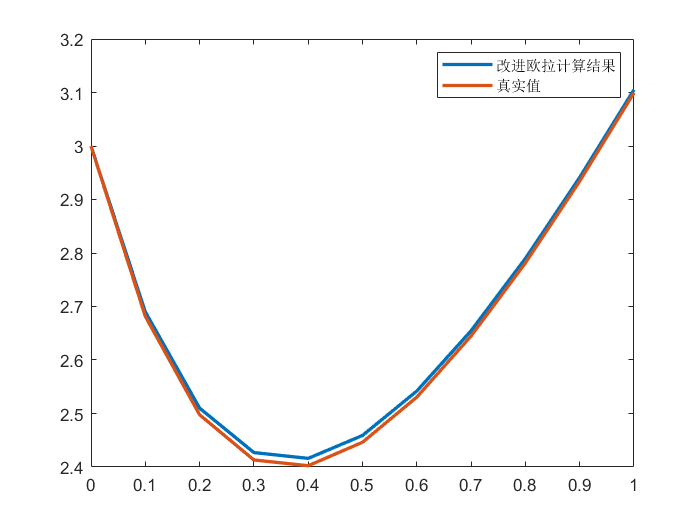

clc,clear,close all
syms x y
dif_f = -3*y+6*x+5;
h = 0.1;
a = 0;
b = 1;
y0 = 3;

y = euler_improve(dif_f,a,b,y0,h);

x = a:h:b;
plot(x,y,'LineWidth',2)
hold on

f = @(x) 2*exp(-3*x) + 2*x +1;
y = f(x);
plot(x,y,'LineWidth',2)
legend('改进欧拉计算结果','真实值')